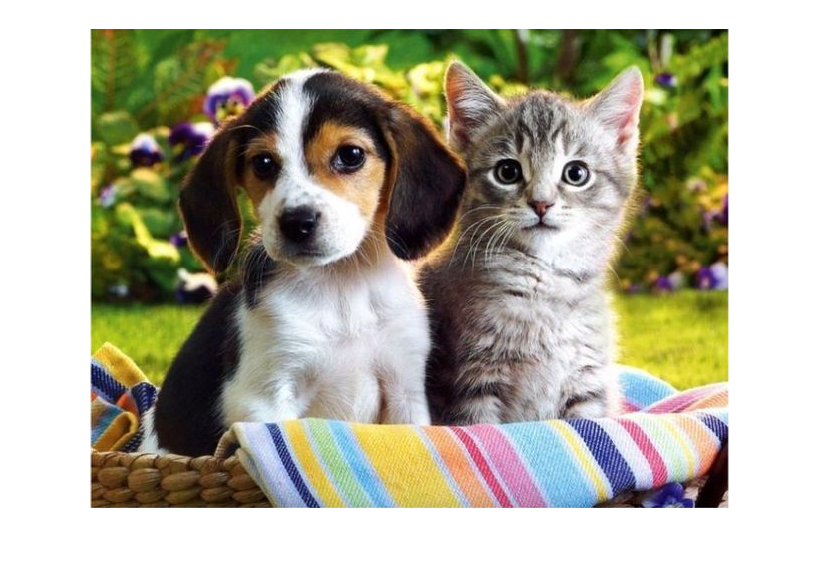

clc; close all; clear all;
Original = imread('imag1.jpg');
r = double(Original(:,:,1))./255;
g = double(Original(:,:,2))./255;
b = double(Original(:,:,3))./255;
A = double(Original)./255;

% Matriz = [0,1,0; 1,-4,1; 0,1,0]; %BORDES
% Matriz = [1,1,1; 1,1,1; 1,1,1]; %DESENFOQUE
% Matriz = [1,1,1; 1,-2,1; -1,-1,-1]; %NORTE
% Matriz = [-1,-1,-1; 0,0,0; 1,1,1]; %Filtro Bordes
% Matriz = [-1, -2, -1; 0,0, 0; 1, 2, 1]; %SOBEL
% Matriz = [1, -2, 1; -2, -5, 0; 1, 1, 1]; %SHARPEN
% Matriz = [0, 0, 0; -1, 1, 0; 0, 0, 0]; %BORDES
Matriz = [0,-1,0; -1,5,-1; 0,-1,0]; %Enfoque
% Matriz = [-2,-1,0; -1,1,1; 0,1,2]; %REPUJADO




[m,n,p] = size(Original);

sumR = zeros(m,n);
sumG = zeros(m,n);
sumB = zeros(m,n);

B = zeros(m,n);

for i=2: m-1
    for j=2:n-1
        sumR(i,j) = (1/9)*Matriz(1,1).*r(i-1,j-1) + (1/9)*Matriz(1,2).*r(i-1,j) + (1/9)*Matriz(1,3).*r(i-1,j+1) ...
        + (1/9)*Matriz(2,1).*r(i,j-1) + (1/9)*Matriz(2,2).*r(i,j) + (1/9)*Matriz(2,3).*r(i,j+1)...
        + (1/9)*Matriz(3,1).*r(i+1,j-1) + (1/9)*Matriz(3,2).*r(i+1,j) + (1/9)*Matriz(3,3).*r(i+1,j+1);

        sumG(i,j) = (1/9)*Matriz(1,1).*g(i-1,j-1) + (1/9)*Matriz(1,2).*g(i-1,j) + (1/9)*Matriz(1,3).*g(i-1,j+1) ...
        + (1/9)*Matriz(2,1).*g(i,j-1) + (1/9)*Matriz(2,2).*g(i,j) + (1/9)*Matriz(2,3).*g(i,j+1)...
        + (1/9)*Matriz(3,1).*g(i+1,j-1) + (1/9)*Matriz(3,2).*g(i+1,j) + (1/9)*Matriz(3,3).*g(i+1,j+1);

        sumB(i,j) = (1/9)*Matriz(1,1).*b(i-1,j-1) + (1/9)*Matriz(1,2).*b(i-1,j) + (1/9)*Matriz(1,3).*b(i-1,j+1) ...
        + (1/9)*Matriz(2,1).*b(i,j-1) + (1/9)*Matriz(2,2).*b(i,j) + (1/9)*Matriz(2,3).*b(i,j+1)...
        + (1/9)*Matriz(3,1).*b(i+1,j-1) + (1/9)*Matriz(3,2).*b(i+1,j) + (1/9)*Matriz(3,3).*b(i+1,j+1);

        B(i,j) = Matriz(1,1).*A(i-1,j-1) + Matriz(1,2).*A(i-1,j) + Matriz(1,3).*A(i-1,j+1) ...
        + Matriz(2,1).*A(i,j-1) + Matriz(2,2).*A(i,j) + Matriz(2,3).*A(i,j+1)...
        + Matriz(3,1).*A(i+1,j-1) + Matriz(3,2).*A(i+1,j) + Matriz(3,3).*A(i+1,j+1);
        B(i,j) = B(i,j)./9;

    end
end

factor = 9;

Convolucion(:,:,1) = sumR*factor;
Convolucion(:,:,2) = sumG*factor;
Convolucion(:,:,3) = sumB*factor;

imshow(Original);

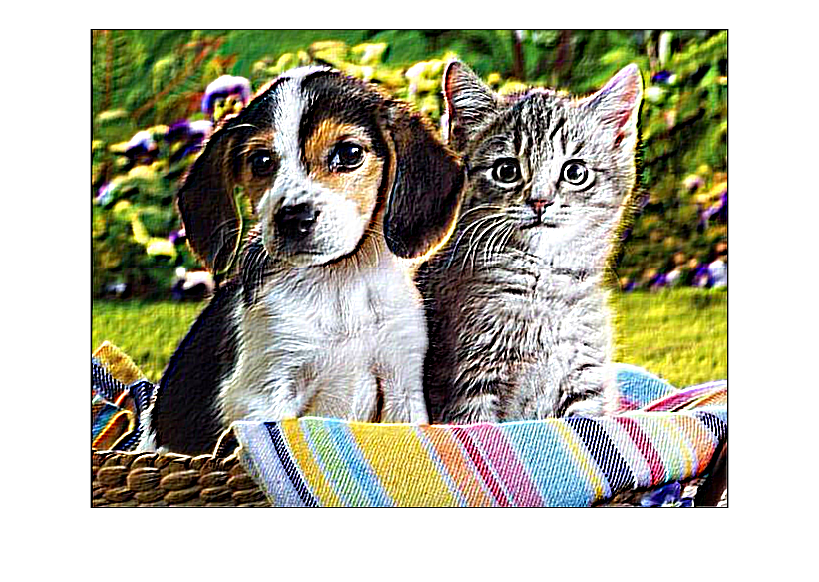

imshow(Convolucion);

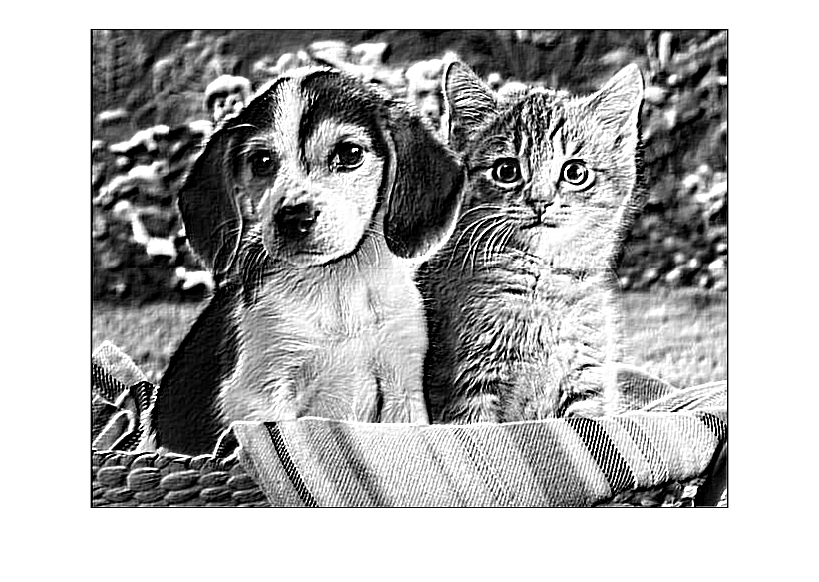

imshow(B*factor);

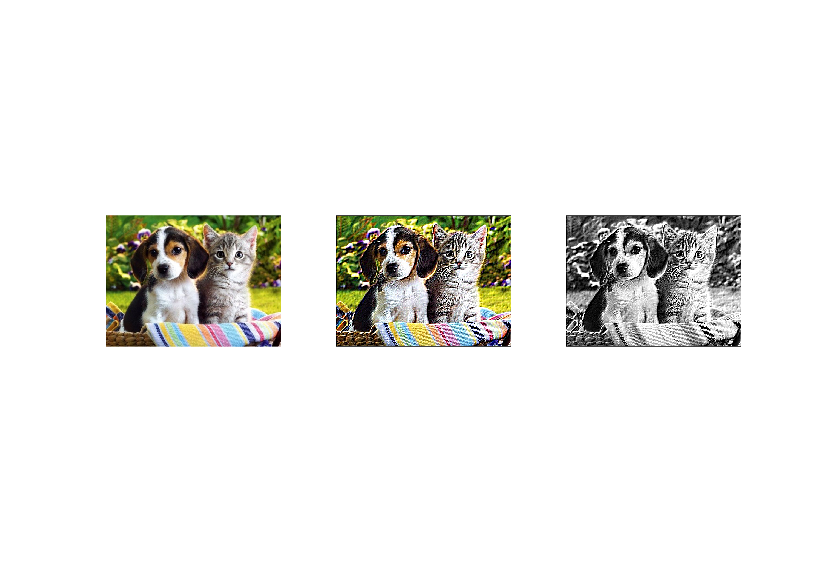


subplot(1,3,1),imshow(Original);
subplot(1,3,2),imshow(Convolucion);
subplot(1,3,3),imshow(B*factor);